# My datastore

clc;
close all;
clear variables;

## Creating a datastore for my images

folder_name = fullfile(pwd, 'data', 'raw');
imds = imageDatastore(folder_name, 'LabelSource',"foldernames");
raw_images = readall(imds);

### Label data 

Get label from filename

imds.Labels = char(imds.Labels); % turn labes to char
N = length(imds.Files);
for i = 1:N
    label = imds.Files{i}(length(folder_name) + 6);
    imds.Labels{i} = label;
end


### Display raw images

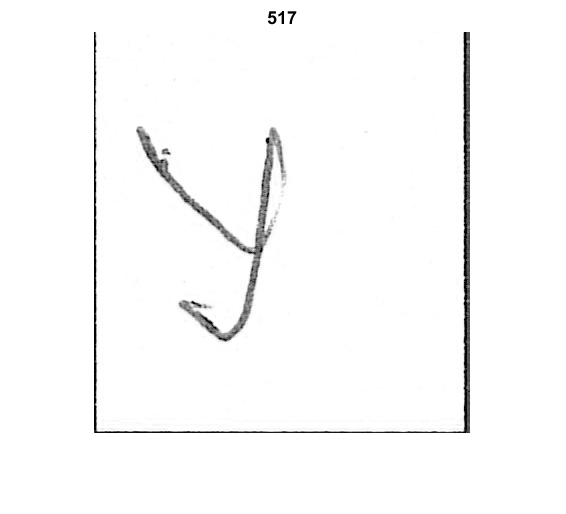

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(raw_images{rand_int})
    title(rand_int)
end

## Preprocessing images

bin_threshold = 0.9;
target_size = [400, 400];
final_size = [64, 64];
sigma = 0.5;
medfilt_size = [5, 5];

gauss_flg = true;
median_flg = true;

preprocessed_imds = transform(imds, @(x) imresize(x, target_size));

if gauss_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) imgaussfilt(x, sigma));
end

preprocessed_imds = transform(preprocessed_imds, @(x) binarization(x, bin_threshold));

if median_flg
    preprocessed_imds = transform(preprocessed_imds, @(x) medfilt2(x, medfilt_size));
end
preprocessed_imds = transform(preprocessed_imds, @edge_removal);

preprocessed_imds = transform(preprocessed_imds, @(x) imresize(x, final_size));



preprocessed_images = my_readall(preprocessed_imds, N);

### Display preprocessed images

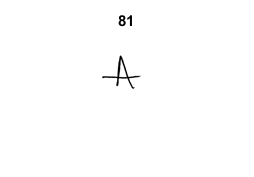

for i=1:1
    figure();
    rand_int = randi(length(imds.Files));
    imshow(preprocessed_images{rand_int})
    title(rand_int)
end

## Feature extraction

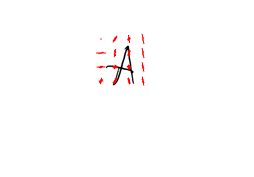

I = preprocessed_images{1};
figure('Position', [10 10 900 600]);
imshow(I);
hold on

% hog surf and kaze are good for classification apparently
% https://www.mathworks.com/help/vision/ug/local-feature-detection-and-extraction.html

method_name = "hog";

num_points = 10;
cell_size = [14, 14];


if method_name == "hog"
    [featureVector, visualization] = extractHOGFeatures(I,'CellSize',cell_size);
    plot(visualization, 'Color','red')
elseif method_name == "surf"
    points = detectSURFFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
elseif method_name == "kaze"
    points = detectKAZEFeatures(I).selectStrongest(num_points);
    [features, valid_points] = extractFeatures(I, points);
    plot(valid_points);
end

if method_name == "hog"
    data = zeros(N, length(featureVector), 'double');
    for i = 1:N
        [feature_vector, ~] = extractHOGFeatures(preprocessed_images{i},'CellSize',cell_size);
        data(i, :) = feature_vector;
    end
end

### Dimensionality reduction

[coeff,~,~,~,explained,~] = pca(data);

coeff =    -0.0069   -0.0096   -0.0005    0.0047   -0.0069   -0.0006   -0.0006   -0.0084   -0.0252   -0.0037   -0.0142   -0.0062   -0.0057   -0.0239   -0.0034   -0.0218   -0.0123    0.0026    0.0047    0.0171   -0.0034   -0.0114    0.0200    0.0272    0.0379    0.0129   -0.0063    0.0136    0.0273    0.0093    0.0004    0.0135   -0.0160    0.0206   -0.0287    0.0055    0.0092    0.0160    0.0222    0.0325    0.0168   -0.0225   -0.0225    0.0110   -0.0369   -0.0002   -0.0277   -0.0001   -0.0162   -0.0248
   -0.0049   -0.0072    0.0031    0.0015   -0.0021   -0.0004   -0.0021    0.0039   -0.0094    0.0043   -0.0032   -0.0027    0.0010   -0.0254   -0.0050    0.0011   -0.0116   -0.0055   -0.0001    0.0034    0.0004   -0.0040    0.0070    0.0122    0.0139    0.0138   -0.0040    0.0122    0.0132    0.0106    0.0061   -0.0002   -0.0024    0.0149   -0.0199    0.0132   -0.0048    0.0111    0.0140    0.0089    0.0160    0.0086    0.0013    0.0176   -0.0140    0.0139   -0.0069   -0.0123   -0.0054 

explained =    17.7778
    9.6642
    9.1277
    6.4595
    6.0256
    4.5683
    3.7871
    2.6487
    2.4298
    2.2857


explained
A_dim_reduction = coeff(:, 1:100);
data_low_dim = data * A_dim_reduction;

sigma_cov = cov(data_low_dim);


## Dividing the dataset

`[trainingSet, validationSet] = splitEachLabel(imds, 0.6, ``'randomize'``); ?`

### Shuffling the dataset

preprocessed_imds = shuffle(preprocessed_imds);
preprocessed_images = my_readall(preprocessed_imds, N);
preprocessed_imds.UnderlyingDatastore.Labels{1:5}

ans = 'O'

ans = 'A'

ans = 'O'

ans = 'A'

ans = 'E'

### Dividing the dataset into training and testing

partition_index = round(N * 0.7);

training_imds = subset(preprocessed_imds, 1:partition_index);
testing_imds = subset(preprocessed_imds, partition_index + 1 :N);